# Integrating MATLAB with AWS Bedrock Models

## Uploading an Image to the AWS Bedrock Model

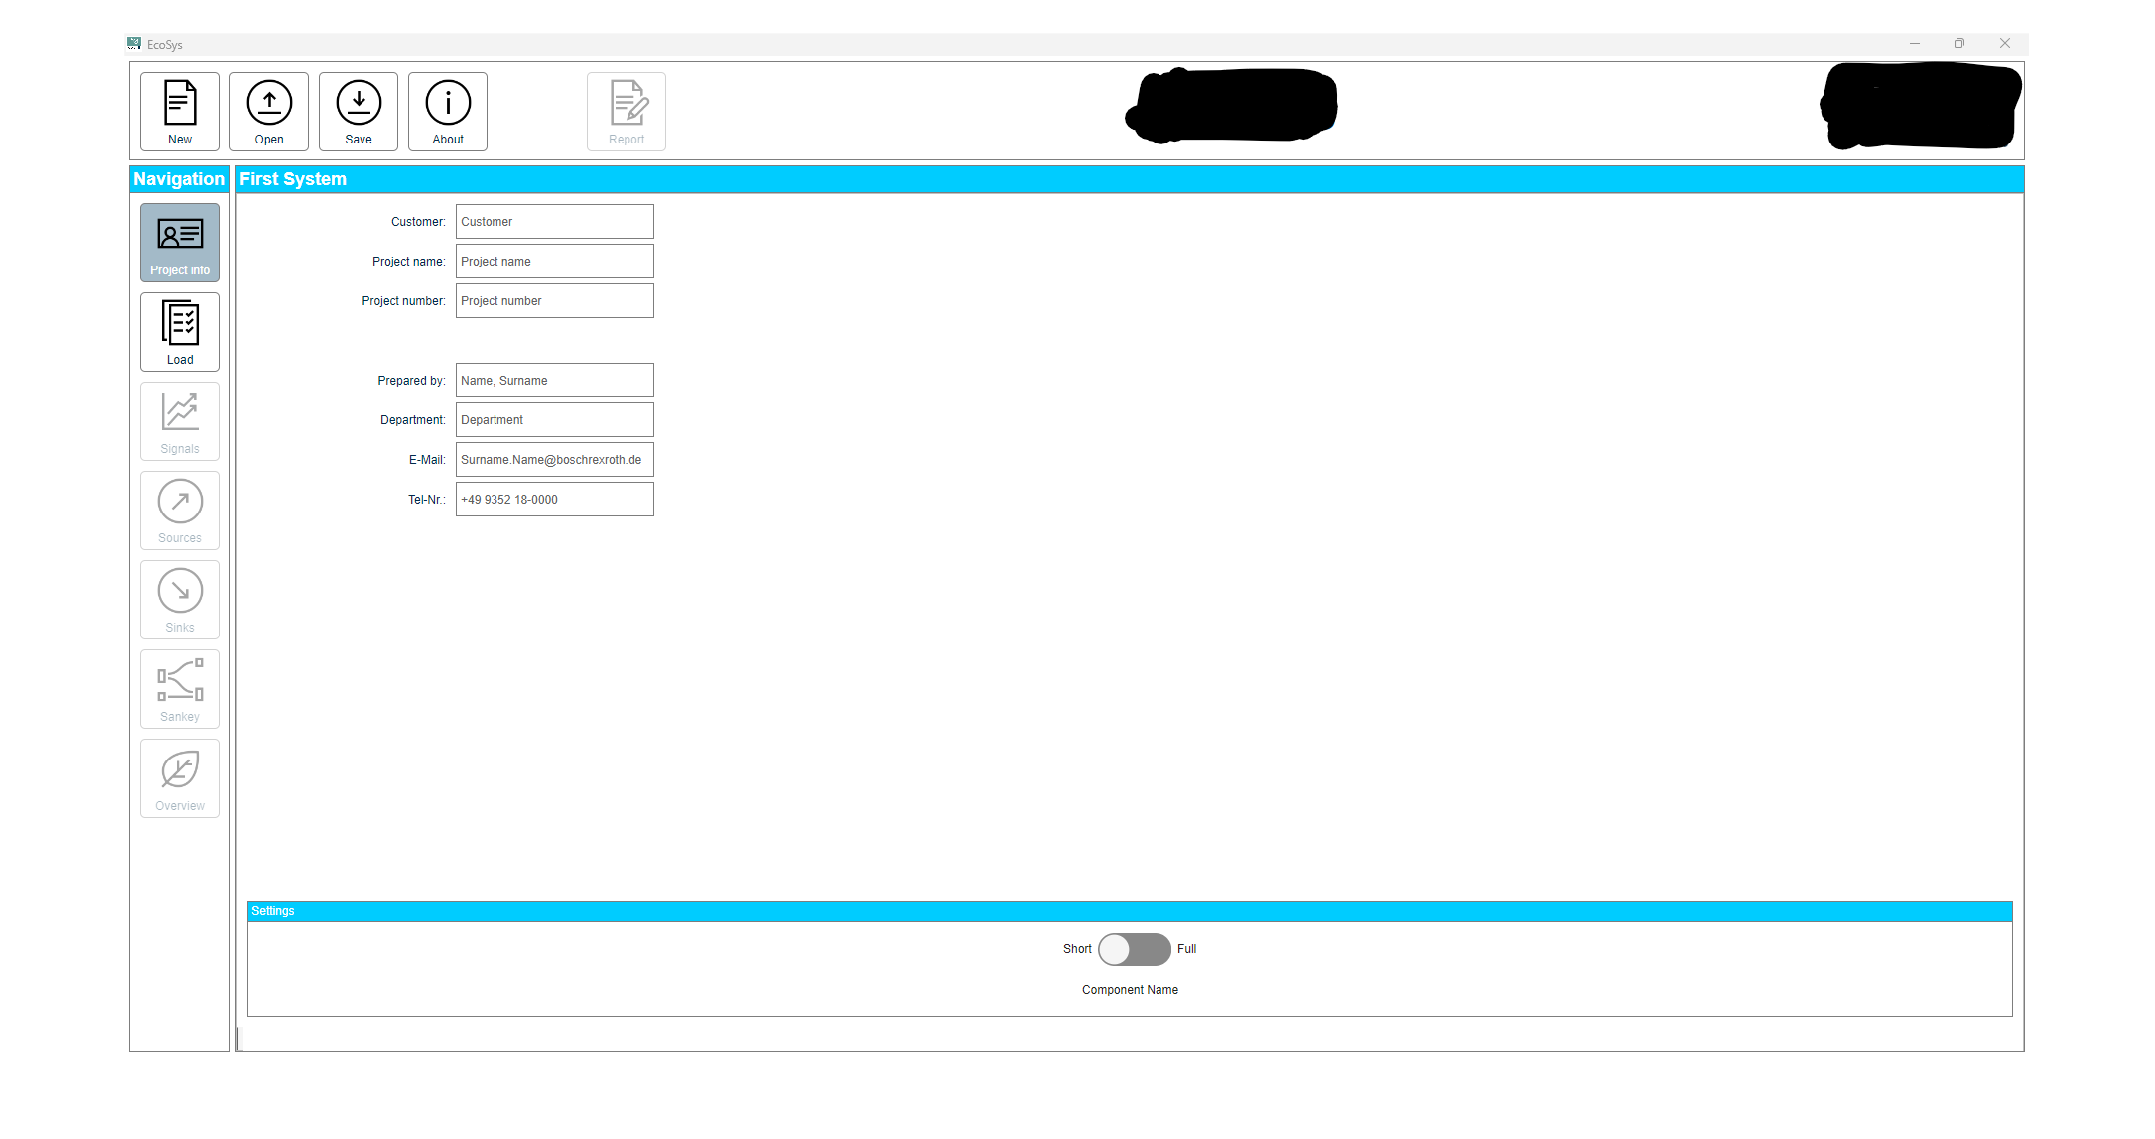

imageName = "C:\Users\sbaskar\Downloads\ecosys_overview.png";
fileId = fopen(imageName, 'rb');

% Check if the file opened successfully
if fileId == -1
    error('Failed to open file: %s', imageName);
else
    % Read the file as uint8
    imageBinary = fread(fileId, inf, 'uint8');
    fclose(fileId); % Always close the file after reading
end

imshow(imageName);

## Interacting with the Model Using the Uploaded Image

message1 = aws.bedrock.runtime.model.Message(imageData = imageBinary, role="user");
bedrock = aws.bedrock.runtime.Client();
fullConversationMessages = aws.bedrock.runtime.model.Message.empty;
fullConversationMessages(end+1) = message1;
response1 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages=message1);
responseMessage1 = response1.message.text

responseMessage1 =     "This image shows a user interface for a software application called "Ecosys". The interface has a top menu bar with options for New, Open, Save, and About. Below that is a navigation panel on the left side with various icons and labels such as Project Info, Load, Signals, and more.
     
     The main content area displays a form titled "First System" with fields for entering project and customer information. These fields include Customer, Project name, Project number, Prepared by, Department, E-Mail, and Tel-Nr. Some of these fields are pre-filled with placeholder text.
     
     At the bottom of the screen, there's a section labeled "Settings" with a toggle switch for "Short/Full" and an input field for "Component Name".
     
     The overall design uses a blue and white color scheme, giving it a clean and professional appearance. This interface seems to be designed for managing project information and settings within some kind of engineering or technical en

fullConversationMessages(end+1) = response1.message;

## Analyzing the Model's Response

secondPrompt = "Provide the html, js, css of this UI with same style and match the picture in all alignments and layouts in a responsive way. ";

message2 = aws.bedrock.runtime.model.Message("text",secondPrompt);
fullConversationMessages(end+1) = message2;
response2 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage2 = response2.message.text

responseMessage2 =     "Here's a basic HTML, CSS, and JavaScript implementation that approximates the UI shown in the image. Note that this is a simplified version and may need further refinement to exactly match all details:
     
     HTML:
     ```html
     <!DOCTYPE html>
     <html lang="en">
     <head>
         <meta charset="UTF-8">
         <meta name="viewport" content="width=device-width, initial-scale=1.0">
         <title>Ecosys</title>
         <link rel="stylesheet" href="styles.css">
     </head>
     <body>
         <div class="container">
             <header>
                 <button>New</button>
                 <button>Open</button>
                 <button>Save</button>
                 <button>About</button>
             </header>
             <main>
                 <nav>
                     <button><img src="project-info-icon.png" alt="Project Info">Project Info</button>
                     <button><img src="load-icon.png" alt="Load">Load</button>
           

fullConversationMessages(end+1) = response2.message;

## Executing MATLAB Computations Based on Analysis

thirdPrompt = "Continue sharing the code ";

message3 = aws.bedrock.runtime.model.Message("text",thirdPrompt);
fullConversationMessages(end+1) = message3;
response3 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage3 = response3.message.text

responseMessage3 =     "Certainly! Here's the continuation of the HTML, followed by the CSS and JavaScript:
     
     HTML (continued):
     ```html
                         <input type="text" id="project-number" name="project-number" placeholder="Project number">
                         
                         <label for="prepared-by">Prepared by:</label>
                         <input type="text" id="prepared-by" name="prepared-by" placeholder="Name, Surname">
                         
                         <label for="department">Department:</label>
                         <input type="text" id="department" name="department" placeholder="Department">
                         
                         <label for="email">E-Mail:</label>
                         <input type="email" id="email" name="email" placeholder="Surname.Name@boschrexroth.de">
                         
                         <label for="tel-nr">Tel-Nr:</label>
                         <input type="tel" 

## Presenting the Computation Results

fullConversationMessages(end+1) = response3.message;
fourthPrompt = "Continue sharing the code ";

message4 = aws.bedrock.runtime.model.Message("text",fourthPrompt);
fullConversationMessages(end+1) = message4;
response4 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage4 = response4.message.text

responseMessage4 =     "Certainly! Here's the continuation of the CSS and the JavaScript:
     
     CSS (styles.css continued):
     ```css
     header {
         background-color: #f0f0f0;
         padding: 10px;
         display: flex;
         gap: 10px;
     }
     
     header button {
         padding: 5px 10px;
         background-color: #fff;
         border: 1px solid #ccc;
         cursor: pointer;
     }
     
     main {
         display: flex;
         flex-grow: 1;
     }
     
     nav {
         width: 200px;
         background-color: #f0f0f0;
         padding: 10px;
         display: flex;
         flex-direction: column;
         gap: 10px;
     }
     
     nav button {
         display: flex;
         align-items: center;
         gap: 5px;
         padding: 5px;
         background: none;
         border: none;
         cursor: pointer;
         text-align: left;
     }
     
     nav button img {
         width: 20px;
         height: 20px;
     }
     
     .co

fullConversationMessages(end+1) = response4.message;

fourthPrompt = "Continue sharing the code if any";

message5 = aws.bedrock.runtime.model.Message("text",fourthPrompt);
fullConversationMessages(end+1) = message5;
response5 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage5 = response5.message.text

responseMessage5 =     "Certainly! Here's the final part of the CSS and the JavaScript:
     
     CSS (styles.css continued):
     ```css
     .switch {
         position: relative;
         display: inline-block;
         width: 60px;
         height: 34px;
     }
     
     .switch input {
         opacity: 0;
         width: 0;
         height: 0;
     }
     
     .slider {
         position: absolute;
         cursor: pointer;
         top: 0;
         left: 0;
         right: 0;
         bottom: 0;
         background-color: #ccc;
         transition: .4s;
     }
     
     .slider:before {
         position: absolute;
         content: "";
         height: 26px;
         width: 26px;
         left: 4px;
         bottom: 4px;
         background-color: white;
         transition: .4s;
     }
     
     input:checked + .slider {
         background-color: #00a0e3;
     }
     
     input:checked + .slider:before {
         transform: translateX(26px);
     }
     
     .slider.ro

fullConversationMessages(end+1) = response5.message;


fourthPrompt = "Continue sharing the code if any";

message6 = aws.bedrock.runtime.model.Message("text",fourthPrompt);
fullConversationMessages(end+1) = message6;
response6 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage6 = response6.message.text

responseMessage6 =     "Certainly! Here's the final part of the JavaScript:
     
     JavaScript (script.js continued):
     ```javascript
         toggleSwitch.addEventListener('change', function() {
             if (this.checked) {
                 componentNameInput.style.display = 'block';
             } else {
                 componentNameInput.style.display = 'none';
             }
         });
     
         // You could also add functionality to the navigation buttons
         const navButtons = document.querySelectorAll('nav button');
         navButtons.forEach(button => {
             button.addEventListener('click', function() {
                 // Remove 'active' class from all buttons
                 navButtons.forEach(btn => btn.classList.remove('active'));
                 // Add 'active' class to clicked button
                 this.classList.add('active');
                 // Here you would typically load different content based on which button was clicked
        

fullConversationMessages(end+1) = response6.message;

fourthPrompt = "Continue sharing the code, if any ";

message7 = aws.bedrock.runtime.model.Message("text",fourthPrompt);
fullConversationMessages(end+1) = message7;
response7 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage7 = response7.message.text

responseMessage7 =     "I apologize for the confusion. There isn't any more code to share for this particular implementation. The HTML, CSS, and JavaScript I've provided earlier form a complete basic implementation of the UI shown in the image.
     
     To recap, we have:
     
     1. HTML: Provides the structure of the page, including the header, navigation, main content area with the form, and footer.
     
     2. CSS (styles.css): Styles the HTML elements to match the layout and design shown in the image.
     
     3. JavaScript (script.js): Adds basic interactivity to the UI, such as handling the toggle switch and button clicks.
     
     These three components together should give you a responsive web page that closely resembles the UI in the image. 
     
     If you want to enhance this implementation further, you could consider:
     
     1. Adding more detailed styling to match the exact look of the original UI.
     2. Implementing more complex interactions and functio

fullConversationMessages(end+1) = response7.message;